# UAV Selection Based on Harmonic Mean

clc
clear all
close all

## Initialization

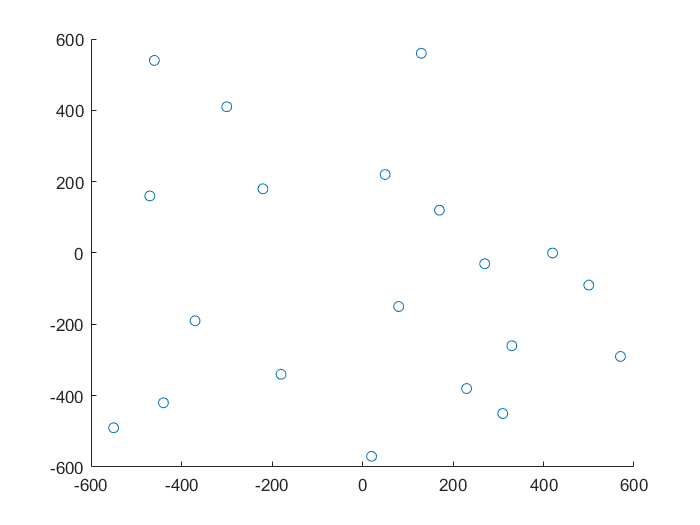

num_bit = 1;
UAV_N = 20;
freq = 2e09; % GHz
gamma_NF_db = [1:15];
gamma_NF = 10.^(gamma_NF_db/10);

m_AU = 2;
omega_AU = 1;
m_UB = 1;
omega_UB = 2;

pl_exponent = 2; % for LOS

GU_A_coor = [-600, 0, 0];
GU_B_coor = [+600, 0, 0];
UAV_H = 100; % meter

% Way 1
% UAVs_coor = reshape(601 - randperm(1201, UAV_N*2), [UAV_N, 2]);

% Way 2
coor = [-590:10:590];
UAVs_coor = reshape(coor(randperm(size(coor,2), UAV_N*2)), [UAV_N, 2]);

UAVs_coor = cat(2, UAVs_coor, repmat(UAV_H, [UAV_N, 1]));
figure()
scatter(UAVs_coor(:,1), UAVs_coor(:,2))

## Selection of UAVs

% sigm = 1; % channel variance
% m = 1.5; % Nakagami-m parameter
% thta = 0 + (pi-0).*rand(1,num_bit); % uniform phase
% y = gamrnd(m, sigm/m, 1, num_bit); % amplitude having Gamma distribution
% fading = sqrt(y).*exp(-1i*thta); % Samples for Nakagami-m distribution
% 
% fading_AU = fading;
% fading_UB = fading_AU;

fading_AU = repmat(random('nakagami', m_AU, omega_AU, [1, num_bit]), 1, UAV_N);
fading_UB = repmat(random('nakagami', m_UB, omega_UB, [1, num_bit]), 1, UAV_N);

dist_AU = vecnorm((repmat(GU_A_coor, UAV_N,1) - UAVs_coor)');
dist_UB = vecnorm((repmat(GU_B_coor, UAV_N,1) - UAVs_coor)');
path_loss_AU = ((3e08/(4*pi*freq))^2) * dist_AU.^(-pl_exponent);
path_loss_UB = ((3e08/(4*pi*freq))^2) * dist_UB.^(-pl_exponent);

h_AU = fading_AU .* sqrt(path_loss_AU);
h_UB = fading_UB .* sqrt(path_loss_UB);

gamma_AU = (abs(h_AU).^2)*gamma_NF(10);
gamma_UB = (abs(h_UB).^2)*gamma_NF(10);

gamma_i = 1./gamma_AU + 1./gamma_UB;
% Selection
[argvalue, argmax] = max(gamma_i);

selected_uav = argmax

selected_uav = 5

selected_uav_coor = UAVs_coor(selected_uav, :)

selected_uav_coor =    570  -290   100


## Calculate Throughput of Selected UAV

gamma_hat_AU = omega_AU*path_loss_AU(selected_uav)*gamma_NF(10)/m_AU;
gamma_hat_UB = omega_UB*path_loss_UB(selected_uav)*gamma_NF(10)/m_UB;

g = gamma_i(selected_uav);
gamma_CDF_ = gamma_CDF(g, gamma_hat_AU ,gamma_hat_UB, m_AU, m_UB)

gamma_CDF_ = 1

## Plots

### Plot System model with UAVs

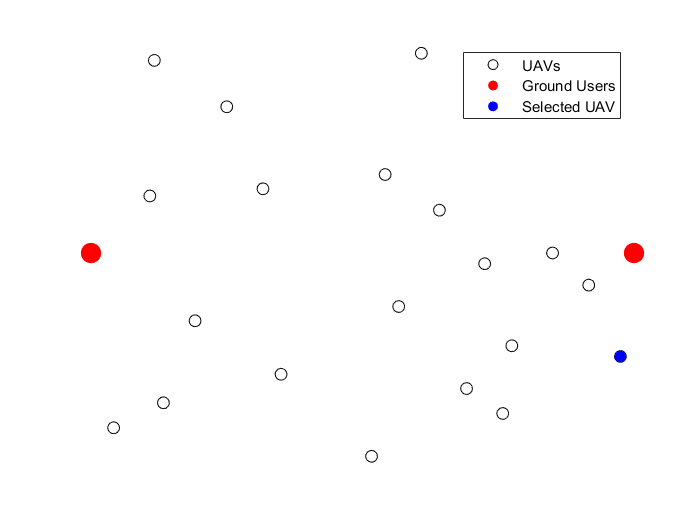

figure()
scatter(UAVs_coor(:,1), UAVs_coor(:,2), 50, 'black')
hold on
GU_coor = cat(1, GU_A_coor, GU_B_coor);
scatter(GU_coor(:,1), GU_coor(:,2), 150, 'red', 'filled')
scatter(selected_uav_coor(:,1), selected_uav_coor(:,2), 50, 'blue', 'filled')
axis off
legend('UAVs', 'Ground Users', 'Selected UAV')